GBM8770 - Projet Automne 2019

# Multi-Scale Line Detector

Patenaude Valérie 1896917

Nom Prénom XXXXXXX

## Partie I: Implémentation de la MSLD

#### Préparatifs

**Q1.** La valeur du masque est : 

% 
% msld.W = 15;
% mask_mean = msld.avg_mask;


**Q2. ########Explications#######**

W = 15;
L = (1:W);
n_orientation = 12; 
msld = MSLD(W,L,n_orientation);         

**Q3.** 

[train, test] = load_dataset()

train = 1×20 struct array with fields:
    namedatalabelmask
    name
    data
    label
    mask


test = 1×20 struct array with fields:
    namedatalabelmask
    name
    data
    label
    mask


I1 = train(1)

I1 = struct with fields:
    namedatalabelmask: []
                 name: '21.png'
                 data: [584×565×3 uint8]
                label: [584×565 logical]
                 mask: [584×565 logical]


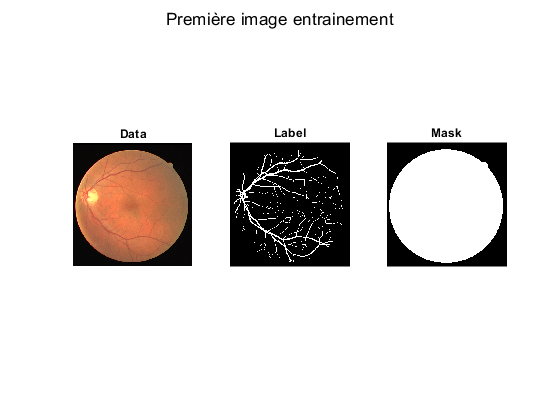

figure(), subplot(1, 3, 1);
imshow(I1.data, [])
title('Data')
subplot(1, 3, 2)
imshow(I1.label, [])
title('Label')
subplot(1, 3, 3)
imshow(I1.mask, [])
title('Mask')
sgtitle('Première image entrainement')

**Q4.** 

**Q5.** 

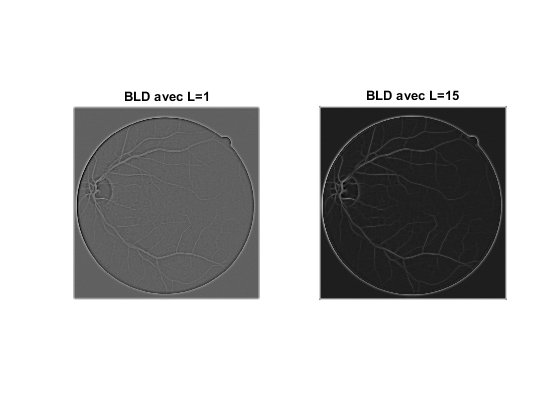

grey_lvl = 255-I1.data(:,:,2);
L = 1;
R_L1 = basicLineDetector(msld,grey_lvl,L);

L = 15;
R_L15 = basicLineDetector(msld,grey_lvl,L);

figure(), subplot(1, 2, 1);
imshow(R_L1)
title('BLD avec L=1')
subplot(1, 2, 2)
imshow(R_L15)
title('BLD avec L=15')

**************************************On peut constater que la segmentation est meilleure lorsque L=1 que lorsque L=15. On peut expliquer cela par le fait qu'avec des petites lignes on reste dans un voisinage plus petit, donc on a moins l'influence des pixels autours, ce qui permet de détecter les plus petits détails alors qu'avec L=15 on considère davantage l'environnement donc l'image est plus floue.

**Q6.** 

**Q7**

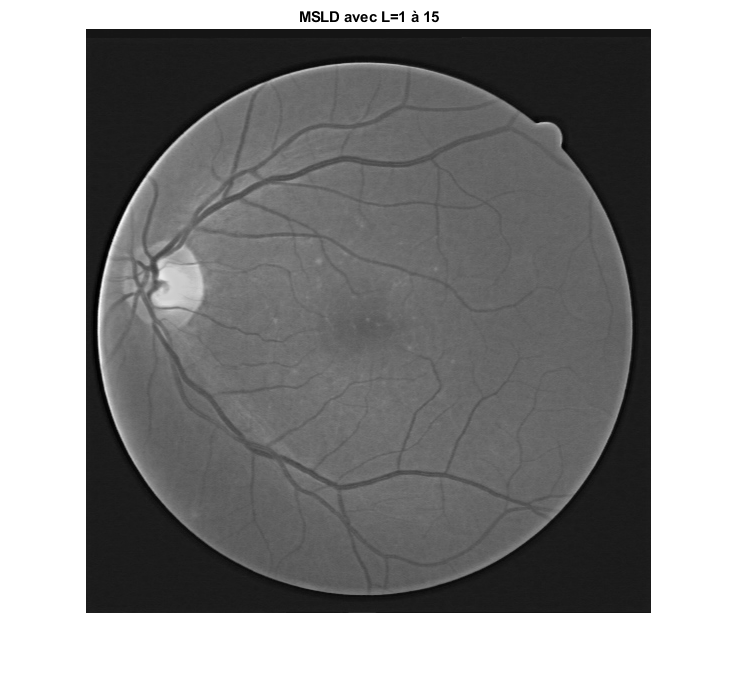

Rcombined = multiScaleLineDetector(msld, I1.data(:,:,2));
figure(),
imshow(Rcombined,[])
title('MSLD avec L=1 à 15')